clc; clear; close all;
A1 = 1; f1 = 2;
A2 = 2; f2 = 5;
A3 = 3; f3 = 8;
A4 = 4; f4 = 12;
fs = 72;
ts = 1/fs; % Thời gian lấy mẫu
t = 0:ts:5;
x1 = A1*sin(2*pi*f1*t);
x2 = A2*sin(2*pi*f2*t);
x3 = A3*sin(2*pi*f3*t);
x4 = A4*sin(2*pi*f4*t);
xn = x1 + x2 + x3 + x4;
% ========= THIẾT KẾ LỌC THẤP QUA THAM CHIẾU TƯƠNG TỰ ==============
sigma_p = 0.02;
sigma_s = 0.02;
f_p = 1;
f_s = 2;
OMEGA_p = 2*pi*f_p ; % Tìm omega P
OMEGA_s = 2*pi*f_s; % Tìm omega s

% ---------------- Bậc lọc và tần số cắt
TS = log10(((1 - (1 - sigma_p) ^ 2) * sigma_s ^ 2) / (1 - sigma_p) ^ 2 * (1-sigma_s ^ 2) )

TS = -4.7829

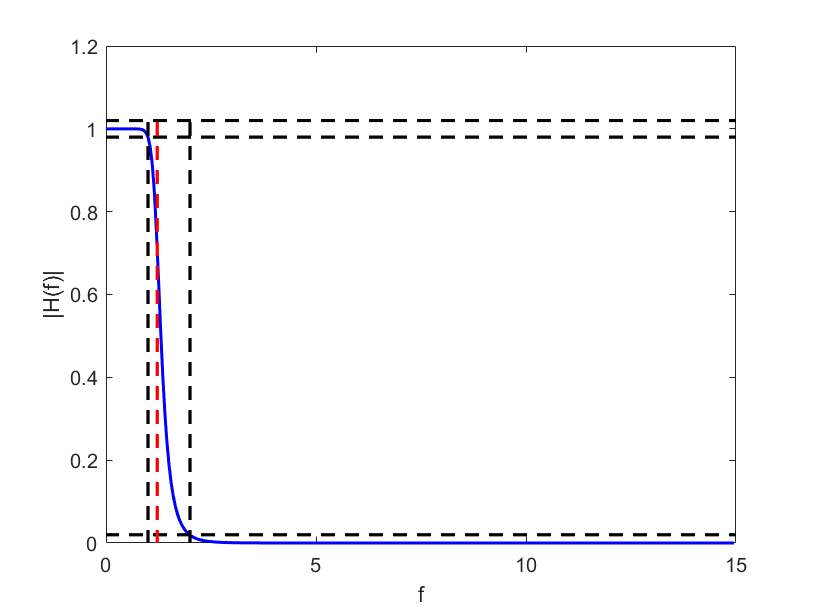

MS = log10(OMEGA_p/OMEGA_s);
N = (1/2)*(TS/MS);
N = fix(N) + 1; % Làm tròn bậc lọc
MS = ((1 - (1 - sigma_p)^2)/(1 - sigma_p)^2)^(1/(2*N));
OMEGA_c = OMEGA_p/MS;  
f_c = OMEGA_c / (2 * pi); % Chuyển tần số góc về Hz

% ---------------- Hàm số chuyển Ha(s)
syms s sp u W w; % u là z^-1
T = 1; % Biến để tích các nhân tử
% Các cực si của hàm truyền H(s) được tính từ Butterworth
for i = 1:N
    si = OMEGA_c * exp(1i * ((2 * i + N - 1) / (2*N)) * pi); % Định nghĩa các cực si
    T = T * (s - si); % Tạo đa thức với các cực
end
Ha_sTQ = (OMEGA_c ^ N) / T;% Hàm số chuyển thấp qua tham chiếu H(s)

% ---------------- Hàm truyền đạt trong miền tần số
Ha_jW = subs(Ha_sTQ,1i * W); % Chuyển qua miền tần số H(jW)


% ---------------- Vẽ đồ thị đáp ứng biên độ
f = 0.001:1/20:15; % Dải tần số
W_val = 2 * pi * f; % Chuyển tần số thành W
Ha_jW = subs(Ha_jW, W, W_val); % Thay giá trị W vào hàm
Ha_jW = double(Ha_jW); % Đưa về dạng số thực

figure(1);
plot(f,abs(Ha_jW),'b-','linewidth',1.5);
line([0 15],[1-sigma_p 1-sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([0 15],[1+sigma_p 1+sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([0 15],[sigma_s sigma_s],'Color','black','LineStyle','--','linewidth',1.6);

line([f_p f_p],[0 1+sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([f_s f_s],[0 1+sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([f_c f_c],[0 1+sigma_p],'Color','red','LineStyle','--','linewidth',1.6);
xlabel('f'); ylabel('|H(f)|');
xlim([0,15])


% ======================= LỌC CAO QUA TƯƠNG TỰ CẦN THIẾT KẾ ======================
fc_p = 11.8;
OMEGAc_p = 2*pi*fc_p;
s = (OMEGA_c * OMEGAc_p) / sp; % Giá trị s mới của lọc thấp qua cần thiết kết theo s'
Ha_s = subs(Ha_sTQ,s); % Hàm chuyển của lọc thấp qua cần thiết kế

% =========================== LỌC CAO QUA SỐ CẦN THIẾT KẾ =========================
% ----- Hàm truyền đạt H(z)
sz = (2 / ts) * ((1 - u) / (1 + u)); % Thay giá trị s của phương pháp biến đổi song tuyến
Hz = subs(Ha_s,sz);
Hz = simplify(Hz); % Rút gọn hàm Hz
[HzTs, HzMs] = numden(Hz); % Lấy tử số, Lấy mẫu số của H(z)

% ----- Bộ trọng số (a1,..., aN) (b0,..., bM)
Hz_Ts = expand(HzTs); % Khai triển đa thức
Hz_Ts = vpa(Hz_Ts);
Hz_Ms = expand(HzMs); % Khai triển đa thức
Hz_Ms = vpa(Hz_Ms);
A = coeffs(Hz_Ms);
a = A/A(1);
a = double(real(a)) % Bộ trọng số a

a =     1.0000   -3.1416    5.0714   -5.0688    3.3778   -1.5126    0.4412   -0.0761    0.0059


B = coeffs(Hz_Ts);
b = B/A(1);
b = double(real(b)) % Bộ trọng số b

b =     0.0769   -0.6155    2.1542   -4.3084    5.3855   -4.3084    2.1542   -0.6155    0.0769


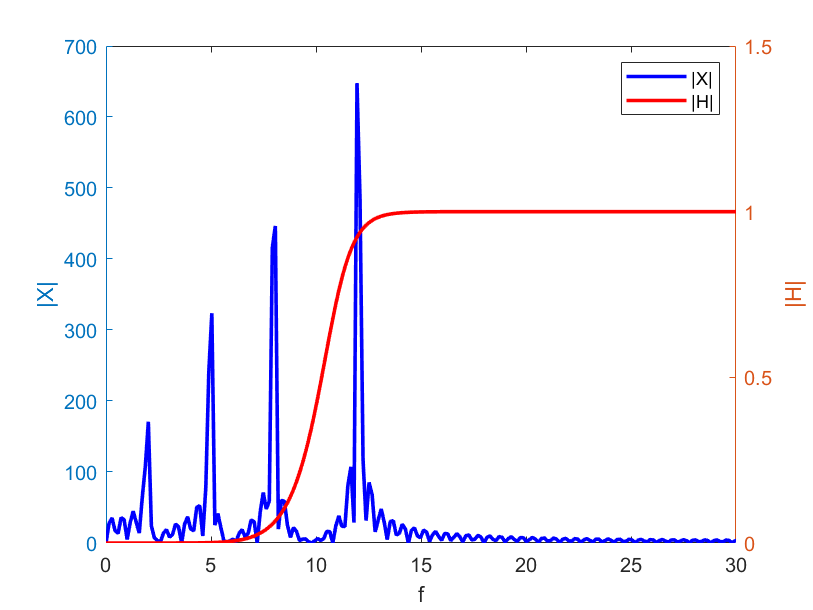


% ----- Phổ DTFT
Nfft = 500;
Xw = fft(xn,Nfft);
Hw = subs(Hz, exp(1i*w)); % Thay z để chuyển H(z)sang H(w)
delta = fs/Nfft;
f = 0:delta:fs/2-delta;
omega = 2*pi*f*ts; % Định nghĩa w của DTFT theo f
Hw_val = subs(Hw,omega);
Hw_val = double(Hw_val);

figure(2)
yyaxis left
plot(f,abs(Xw(1:Nfft/2)),'b-','linewidth',1.8);
xlabel('f'); ylabel('|X|');
yyaxis right;
plot(f,abs(Hw_val),'r-','linewidth',1.8); hold on;
xlabel('f'); ylabel('|H|');
legend('|X|','|H|');
xlim([0,30])
ylim([0,1.5])

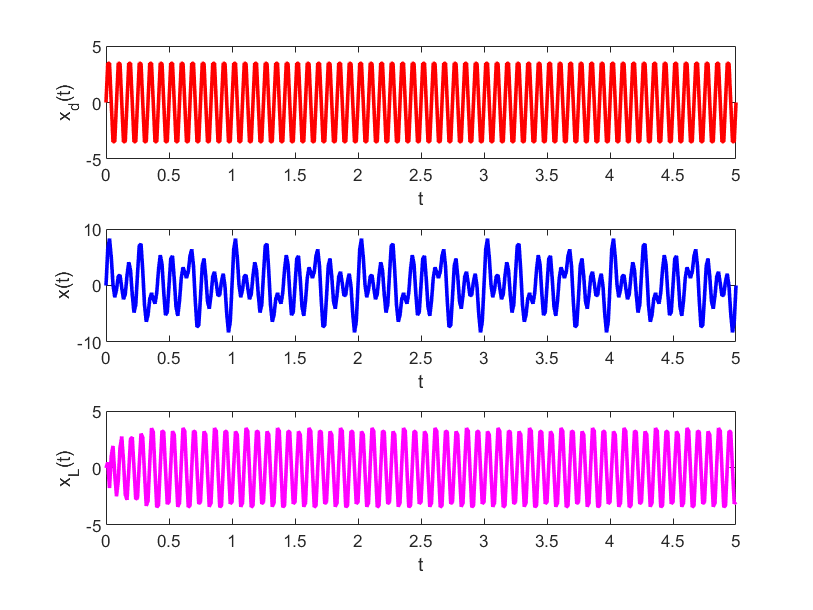

% ========================= TÍN HIỆU NGÕ RA ===============================
xL = filter(b,a,xn);

figure(3)
subplot(3,1,1);
plot(t,x4,'r-','linewidth',1.8);
xlabel('t'); ylabel('x_d(t)');


subplot(3,1,2);
plot(t,xn,'b-','linewidth',1.8);
xlabel('t'); ylabel('x(t)');

subplot(3,1,3);
plot(t,xL(1:length(t)),'m-','linewidth',1.8);
xlabel('t'); ylabel('x_L(t)');